clear;
close all;
clc;

%% Original signal

fs_original = 48000;       % Original sampling frequency
signal_frequency = 7000;   % Signal frequency: 7 kHz
duration = 2;              % Duration in seconds
amplitude = 0.20;          % Keep the volume low

t = 0:1/fs_original:duration-1/fs_original;

x = amplitude * sin(2*pi*signal_frequency*t);

%% Listen to the original signal

disp('Original signal: 7 kHz');

Original signal: 7 kHz



soundsc(x, fs_original);
pause(duration + 1);

%% Select a new sampling frequency

% Change only this value
fs_low = 4000;

% The original frequency must be divisible by fs_low
M = fs_original / fs_low;

if mod(M,1) ~= 0
    error('Choose an fs_low value that divides 48000 exactly.');
end

%% Downsample without an anti-aliasing filter

x_alias = x(1:M:end);

nyquist_frequency = fs_low / 2;

fprintf('New sampling frequency: %.0f Hz\n', fs_low);

New sampling frequency: 4000 Hz


fprintf('New Nyquist frequency: %.0f Hz\n', nyquist_frequency);

New Nyquist frequency: 2000 Hz



%% Listen to the downsampled signal

disp('Downsampled signal');

Downsampled signal


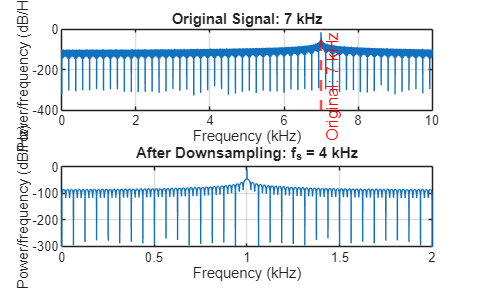


soundsc(x_alias, fs_low);

%% Compare the frequency spectra

figure('Color','white');

subplot(2,1,1);

periodogram(x, [], [], fs_original);
xlim([0 10]);
xline(7, '--r', 'Original: 7 kHz', ...
    'LineWidth', 1.5);

title('Original Signal: 7 kHz');
grid on;

subplot(2,1,2);

periodogram(x_alias, [], [], fs_low);
xlim([0 fs_low/2000]);

title(['After Downsampling: f_s = ', ...
    num2str(fs_low/1000), ' kHz']);

grid on;